# Empirical probability and the law of large numbers 

## 1. (Empirical) Probability of getting a "1" on the dice

In this section, we will see how empirical probabilities approach a priori given probabilities.

### 1.1 Generate dice rolls with uniform random numbers

Output M samples of uniformly distributed random integer sequences in [1, 6]. (length $T$). As an a priori probability, the probability that each of the dice rolls is $1/6$ (assumption of equal weight ratio)

T = 10000;
M = 1000;

d1 = randi([1, 6], [M T]); 

### 1.2 Probability of rolling a 1 on a dice

Let $r(x)$ be the percentage of "1" rolls in the dice up to $x$ times, and draw a graph of $r(x)$ for the first through the fifth samples.

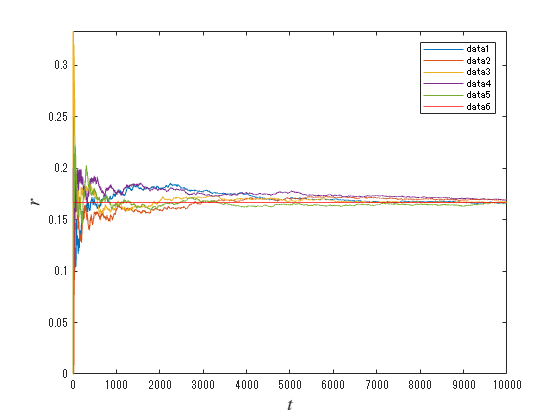

x = 1:T;
r = cumsum(d1==1, 2)./(1:T);

plot(x, r(1:5,:))
hold on 
    yline(1/6, 'r')
hold off
xlabel('$t$', Interpreter='latex', FontSize=14)
ylabel('$r$', Interpreter='latex', FontSize=14)
ylim([0 1/3])
legend()

###  1.3 Square of the difference from the expected value in each sample 

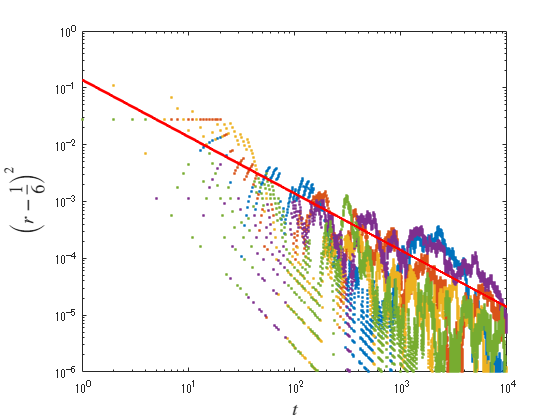

loglog(x, (r(1:5,:)-1/6).^2, '.')
hold on
    loglog(x, (5/36)*x.^(-1), 'r', LineWidth=2)
hold off
xlabel('$t$', Interpreter='latex', FontSize=14)
ylabel('$\left(r-\frac{1}{6}\right)^{2}$', Interpreter='latex', FontSize=14)
xlim([1 T])
ylim([1e-6 1])

## 2. Properties of sample averages: law of large numbers

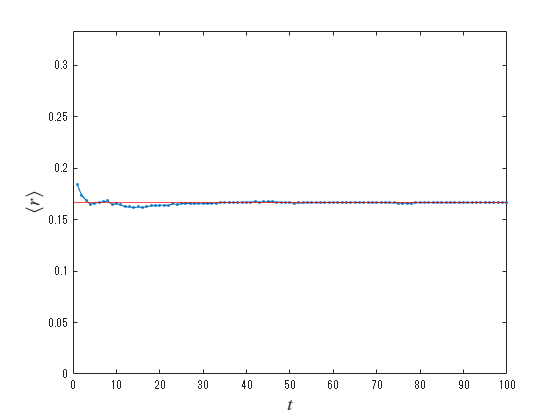

y0 = mean(r,1);
y1 = var(r,0,1);

plot(x, y0, '.-')
hold on 
    yline(1/6, 'r')
hold off
xlabel('$t$', Interpreter='latex', FontSize=14)
ylabel('$\left\langle r \right\rangle$', Interpreter='latex', FontSize=14)
xlim([0 100])
ylim([0 1/3])

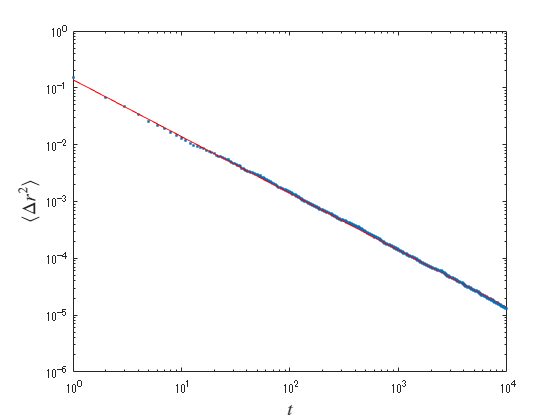


loglog(x, y1, '.')
hold on
    loglog(x, (5/36)*x.^(-1), 'r-')
hold off
xlabel('$t$', Interpreter='latex', FontSize=14)
ylabel('$\left\langle \Delta r^2 \right\rangle$', Interpreter='latex', FontSize=14)
ylim([1e-6 1])